# **Introduction to Computational Medicine: Imaging**

## **Final Project**

**October 11, 2023.**

First, extract the information table of patients from the excel file and the information table of normal and disease subjects, respectively. And then define names of chosen ROI structures and extract (and calculate) the table indices of chosen ROI structures.

% Extract the information table of patients from the excel file.
myTable = readtable("ADNI_ICM_random200.xlsx");

% Extract the information table of normal and disease subjects, respectively.
myTableSort = sortrows(myTable,"x_Diagnosis_","ascend");
for i = 1:size(myTableSort,1)
    if myTableSort{i,"x_Diagnosis_"}{1} ~= "'AD/MCI'"
        diseasenum = i - 1;
        break;
    end
end
disease_table = myTableSort(1:diseasenum,:);
normal_table = myTableSort(diseasenum+1:end,:);

% Define names of chosen ROI structures and extract (and calculate) the table indices of
% chosen ROI structures.
myROI = ["SFG", "MFG", "LFOG", "MFOG", "IFG_opercularis", "IFG_orbitalis", "IFG_triangularis", "PrCG"]; % names of ROI structures
ROI_table = readtable("ROI_fullname.xlsx");

myROI_index = []; % table indices of ROI structures
for i = 1:size(myROI,2)
    for j = 1:size(ROI_table,1)
        if ROI_table{j,'SelectedParcellations_'}{1} == myROI(i)
            myROI_index = [myROI_index, j];
            break;
        end
    end
end
myROI_index = [myROI_index, myROI_index+size(ROI_table,1)];

Within each structure, compute the volume means and standard deviations of each ROI structure for the control/healthy subjects, which are stored in the table variables named stattable.

% Calculate the mean and SD for each structure.
volume_normal = table2array(normal_table(:,5:end));
mean_normal = mean(volume_normal);
SD_normal = std(volume_normal);

% Present the mean and SD of chosen structures for healthy/control subjects.
ROI_name =  myTableSort.Properties.VariableDescriptions(myROI_index+4);
stattable = table(ROI_name', mean_normal(myROI_index)', SD_normal(myROI_index)', 'VariableNames', {'sturctures', 'mean', 'SD'});
disp(stattable);

           sturctures            mean       SD  
    ________________________    ______    ______

    {''SFG_R''             }    8369.5    1190.3
    {''MFG_R''             }    7898.3    1452.1
    {''LFOG_R''            }    3931.1    565.36
    {''MFOG_R''            }    3966.5    479.76
    {''IFG_opercularis_R'' }    2727.2    518.55
    {''IFG_orbitalis_R''   }    2588.1     466.2
    {''IFG_triangularis_R''}    2701.2    528.05
    {''PrCG_R''            }     14203    2296.1
    {''SFG_L''             }    9988.8    1254.6
    {''MFG_L''             }    8085.1    1280.7
    {''LFOG_L''            }      4364     503.1
    {''MFOG_L''            }    4162.5    494.43
    {''IFG_opercularis_L'' }    2976.3    612.11
    {''IFG_orbitalis_L''   }    3427.1    592.81
    {''IFG_triangularis_L''}    3018.1    500.43
    {''PrCG_L''            }     11543    1527.5



filename = 'stattable.xlsx';
writetable(stattable, filename, 'Sheet', 'Sheet1');

Then, for each subject (healthy and diseased), compute the z-score relative to this mean/standard deviation.

volume_disease = table2array(disease_table(:,5:end));
z_score_normal = (volume_normal - mean_normal) ./ SD_normal;
z_score_disease = (volume_disease - mean_normal) ./ SD_normal;

These z-scores will give each patient a "bar code". Plot these bar codes as a heat map where black is 0, red is positive and blue is negative. Show some of these bar codes (Here, we show the bar codes of subjects 1-60.).

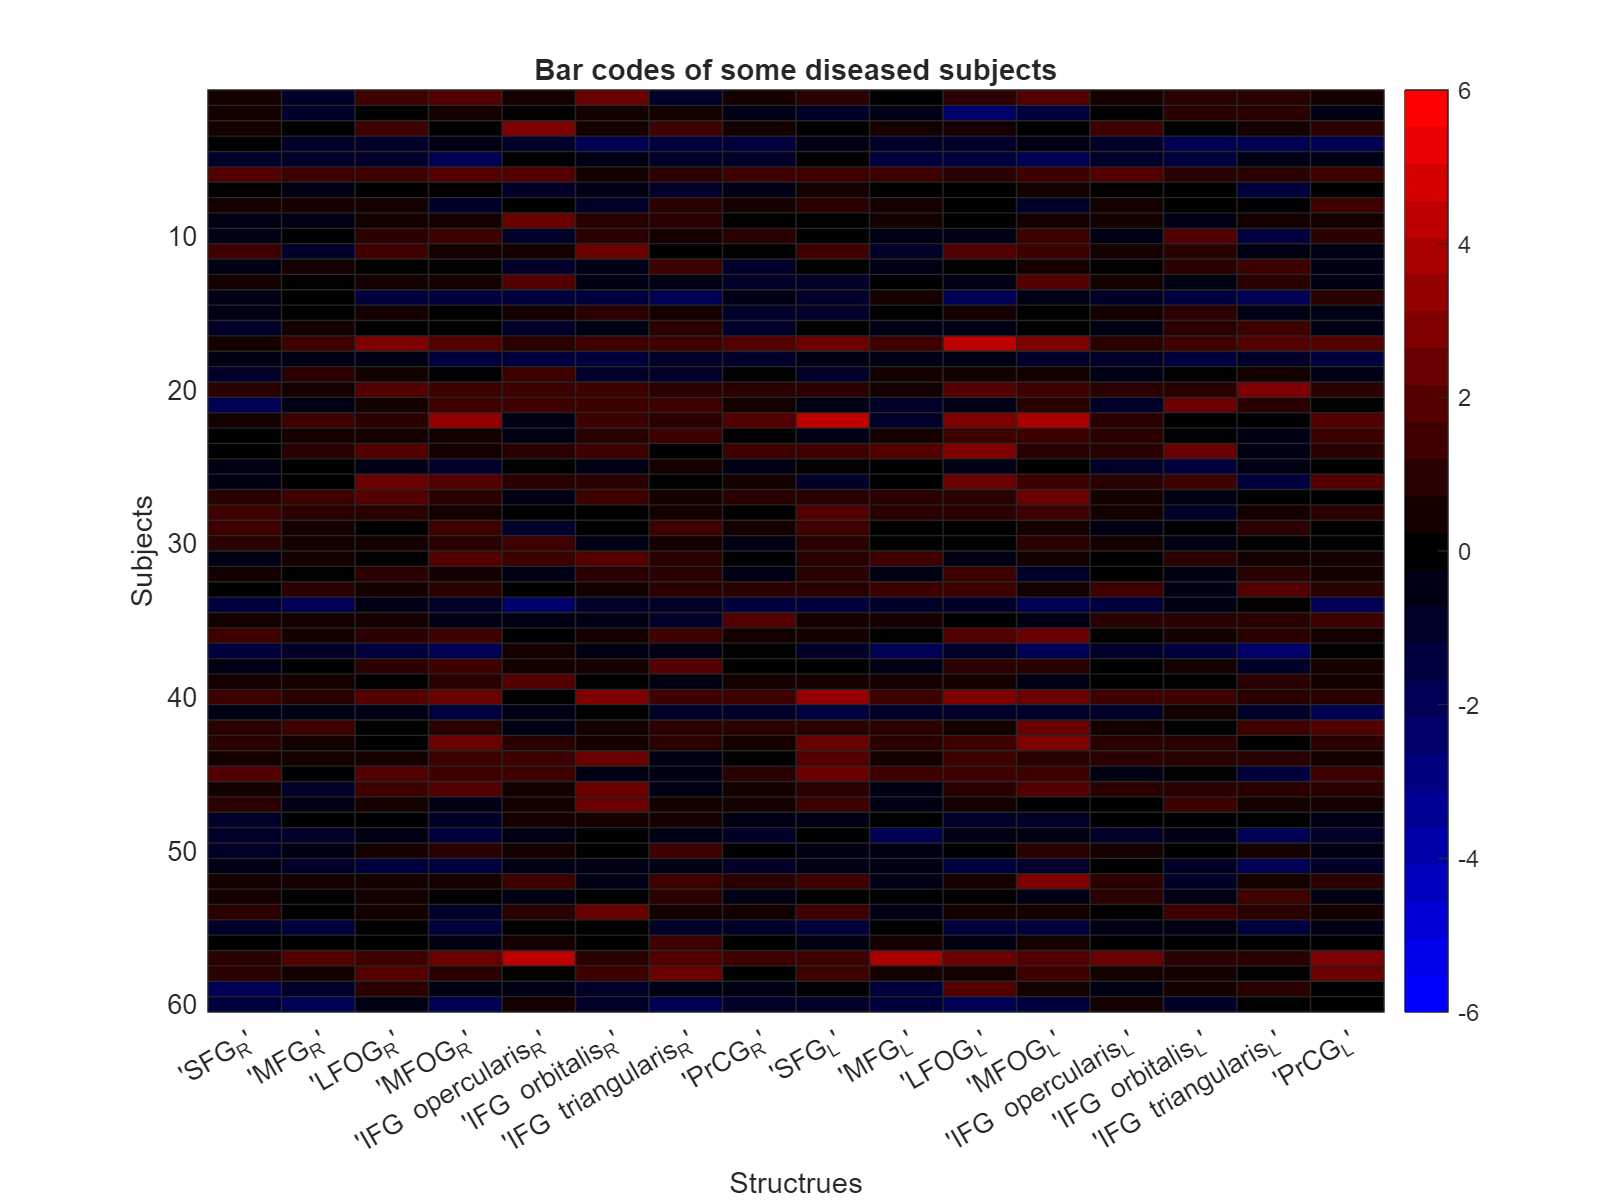

sample_index = 1:60;
sample_disease = z_score_disease(sample_index,myROI_index);
sample_normal = z_score_normal(sample_index,myROI_index);
maxdata = ceil(max(max(sample_normal(:)),max(sample_disease(:))));
mindata = ceil(min(min(sample_normal(:)),min(sample_disease(:))));
maxdata = max(maxdata,-mindata);

positive = [flip((0:1/12:1)') zeros(13, 2)];
negative = [zeros(13, 2) (0:1/12:1)'];
colormap = flip([positive; negative(2:13, :)]); % colormap from smallest to greatest

ROI_name{5} = '''IFG opercularis_R''';
ROI_name{6} = '''IFG orbitalis_R''';
ROI_name{7} = '''IFG triangularis_R''';
ROI_name{5+8} = '''IFG opercularis_L''';
ROI_name{6+8} = '''IFG orbitalis_L''';
ROI_name{7+8} = '''IFG triangularis_L''';

figure('Position', [100, 100, 800, 600]);
h = heatmap(ROI_name, num2cell(sample_index), sample_disease, 'Colormap', colormap);
clim([-maxdata, maxdata]);
title('Bar codes of some diseased subjects');
xlabel('Structrues');
ylabel('Subjects');
YLabels = sample_index;
CustomYLabels = string(YLabels);
CustomYLabels(mod(YLabels,10) ~= 0) = "";
h.YDisplayLabels = CustomYLabels;

saveas(gcf, 'Barcodes for disease subjects.png');

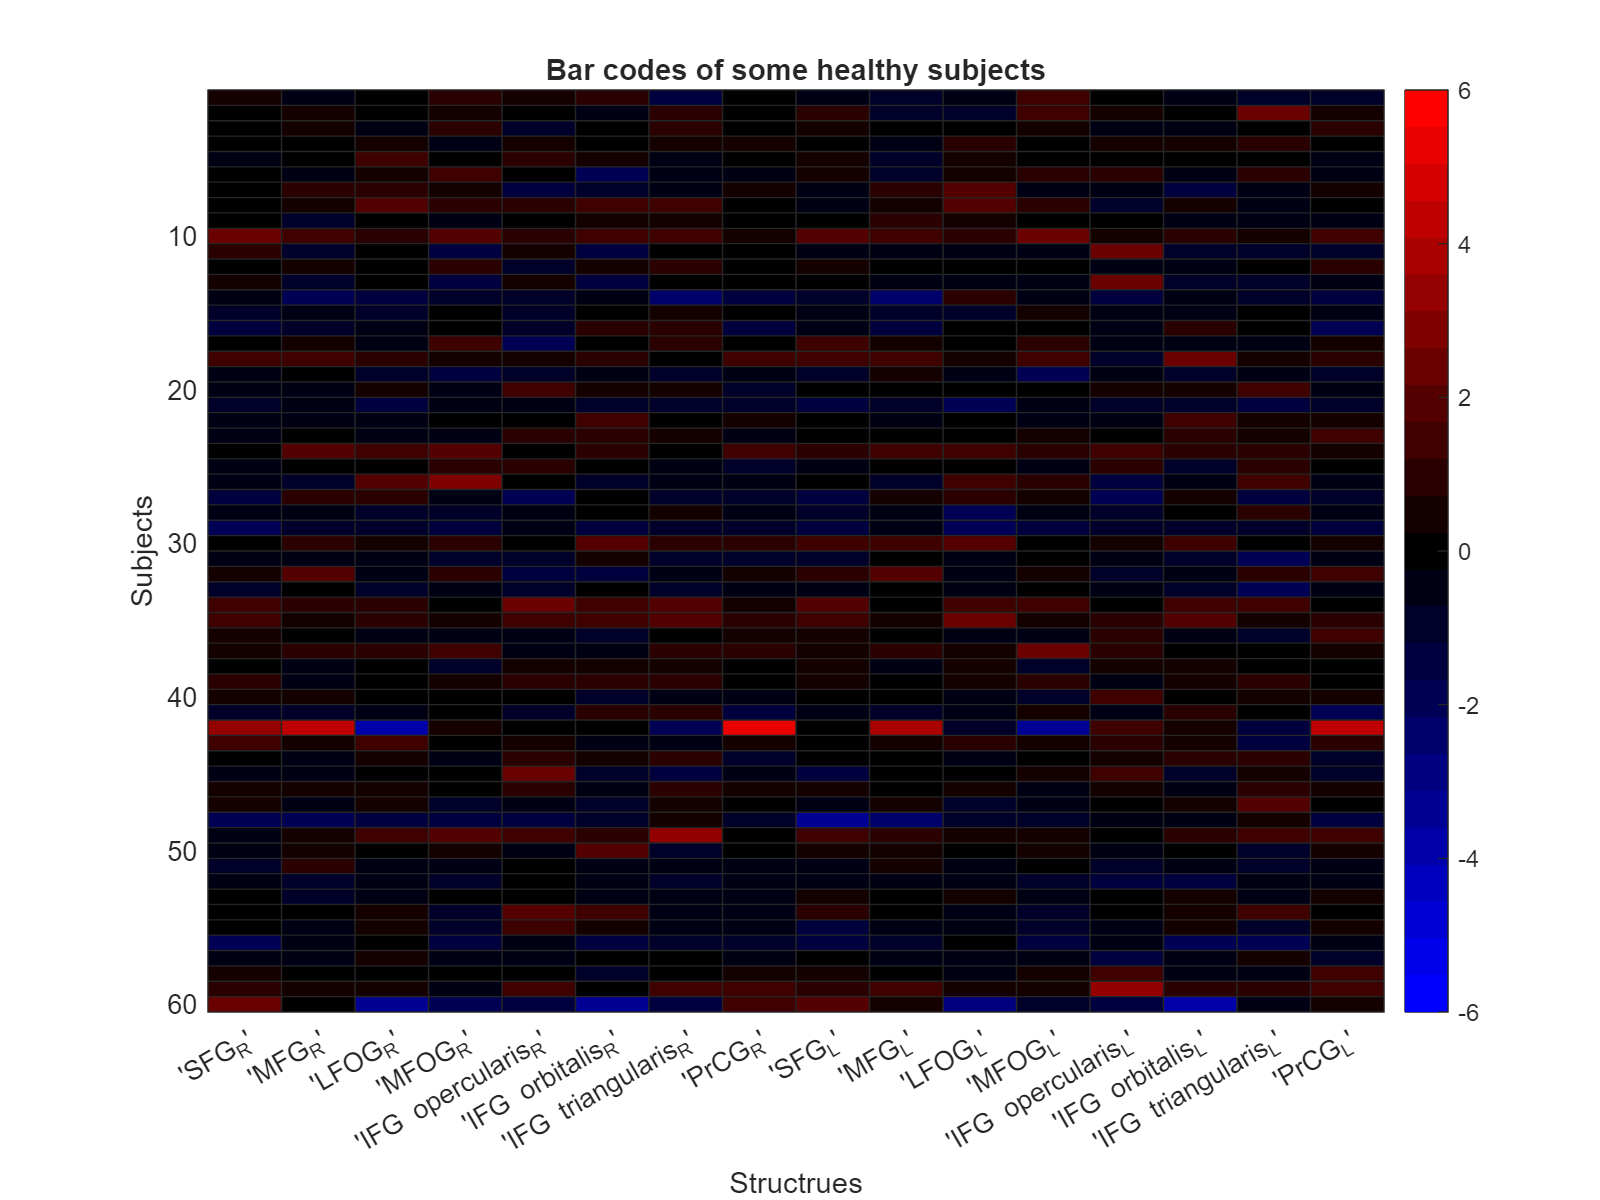

figure('Position', [100, 100, 800, 600]);
h = heatmap(ROI_name, num2cell(sample_index), sample_normal, 'Colormap', colormap);
clim([-maxdata, maxdata]);
title('Bar codes of some healthy subjects');
xlabel('Structrues');
ylabel('Subjects');
YLabels = sample_index;
CustomYLabels = string(YLabels);
CustomYLabels(mod(YLabels,10) ~= 0) = "";
h.YDisplayLabels = CustomYLabels;

saveas(gcf, 'Barcodes for health subjects.png');

Use t-test to compare the structure volumes between the "control" and "disease/disorder" groups. The result of t-test is stored in the array ttest_result with p-values. If the p-value is very small (typically less than the chosen significance level, often denoted as α, which is commonly set at 0.05), it suggests that the observed difference between the sample groups is unlikely to have occurred by random chance alone. In this case, the null hypothesis is rejected and concludes that there is a significant difference between the groups. If the p-value is larger than α, the null hypothesis is true suggesting there is no significant difference between the groups.

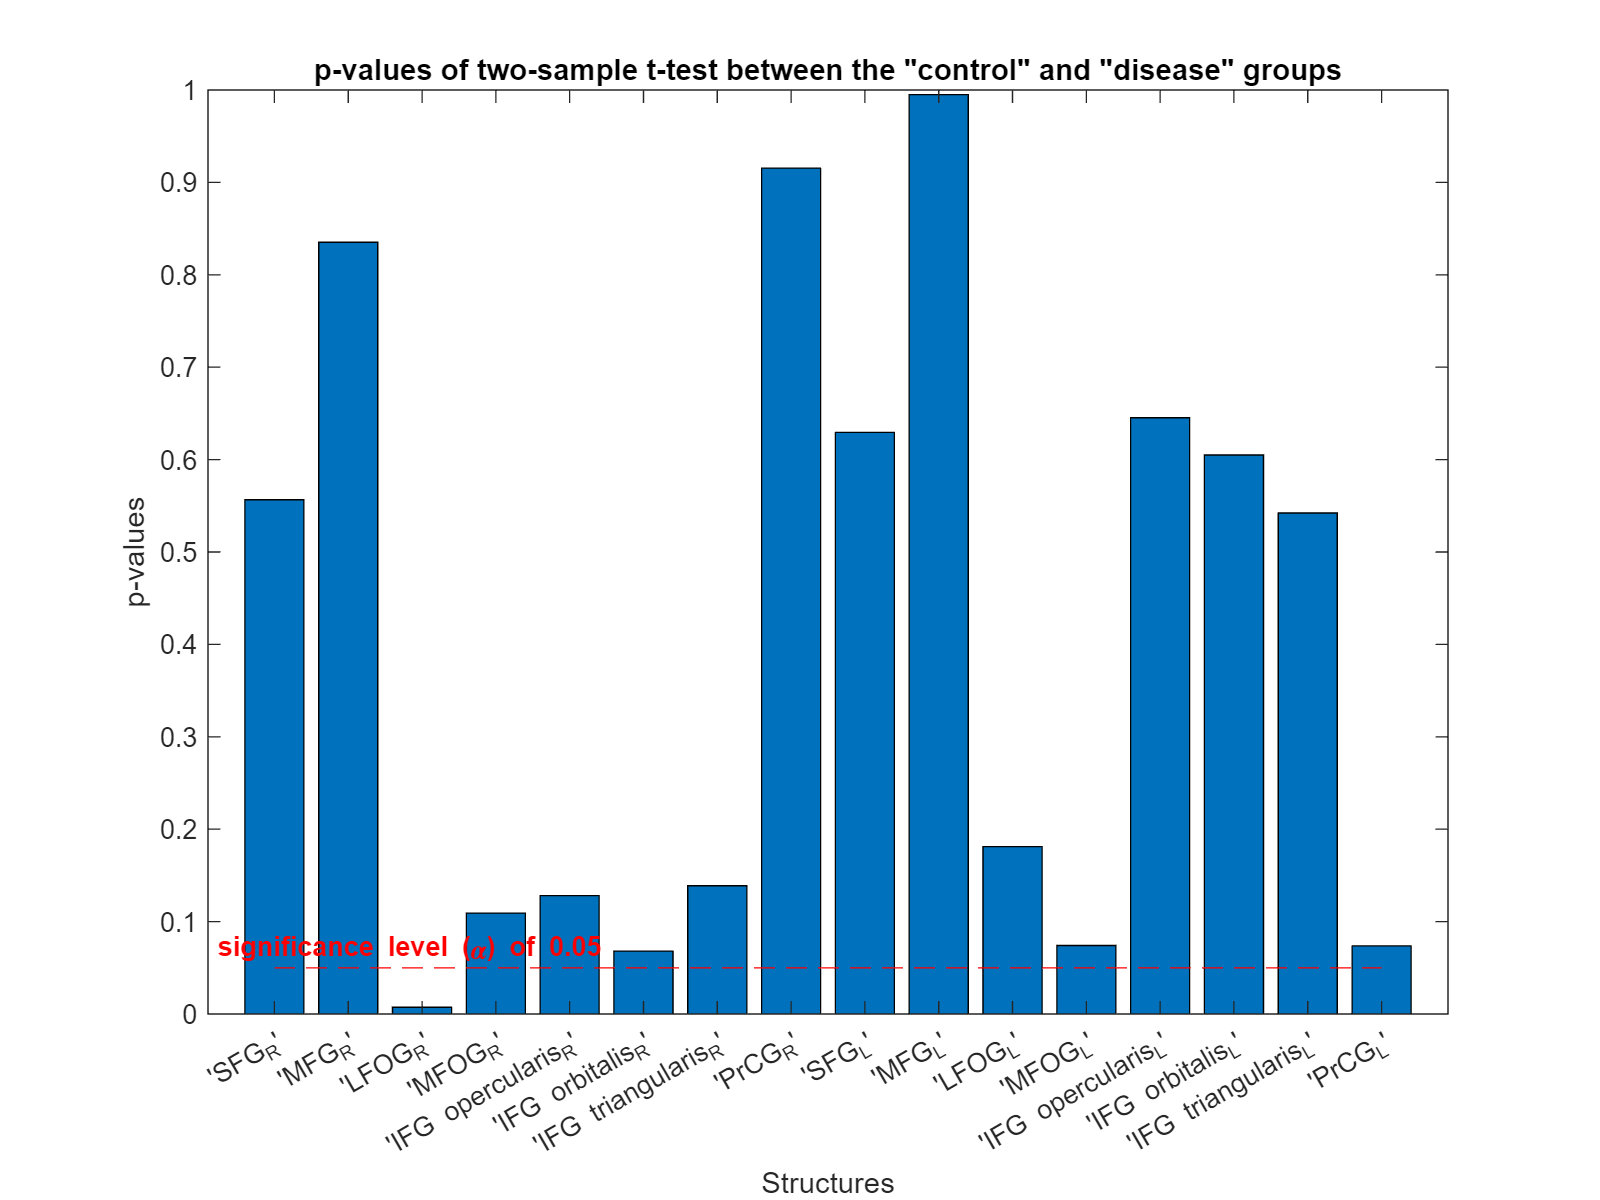

ttest_result = zeros(1,size(volume_normal,2)); % result array of p-values

for i = 1:size(volume_normal,2)
    [~, p] = ttest2(volume_normal(:,i),volume_disease(:,i),'Vartype','unequal');
    ttest_result(i) = p;
end

figure('Position', [100, 100, 800, 600]);
X = categorical(ROI_name);
b = bar(reordercats(X,ROI_name),ttest_result(myROI_index));

title('p-values of two-sample t-test between the "control" and "disease" groups');
xlabel('Structures');
ylabel('p-values');

% Add a horizontal dashed line
line([0, numel(myROI_index) + 1], [0.05, 0.05], 'Color', 'r', 'LineStyle', '--');
% Add a label to the dashed line
text(0.2, 0.05+0.02, 'significance level (\alpha) of 0.05', 'Color', 'r', 'FontWeight', 'bold');

saveas(gcf, 'p-values of t-test.png');

After t-test, differences of means of volume between "control" and "healthy" groups is calculated and shown for each structure to judge whether it is smaller or greater if there is a significance between two groups.

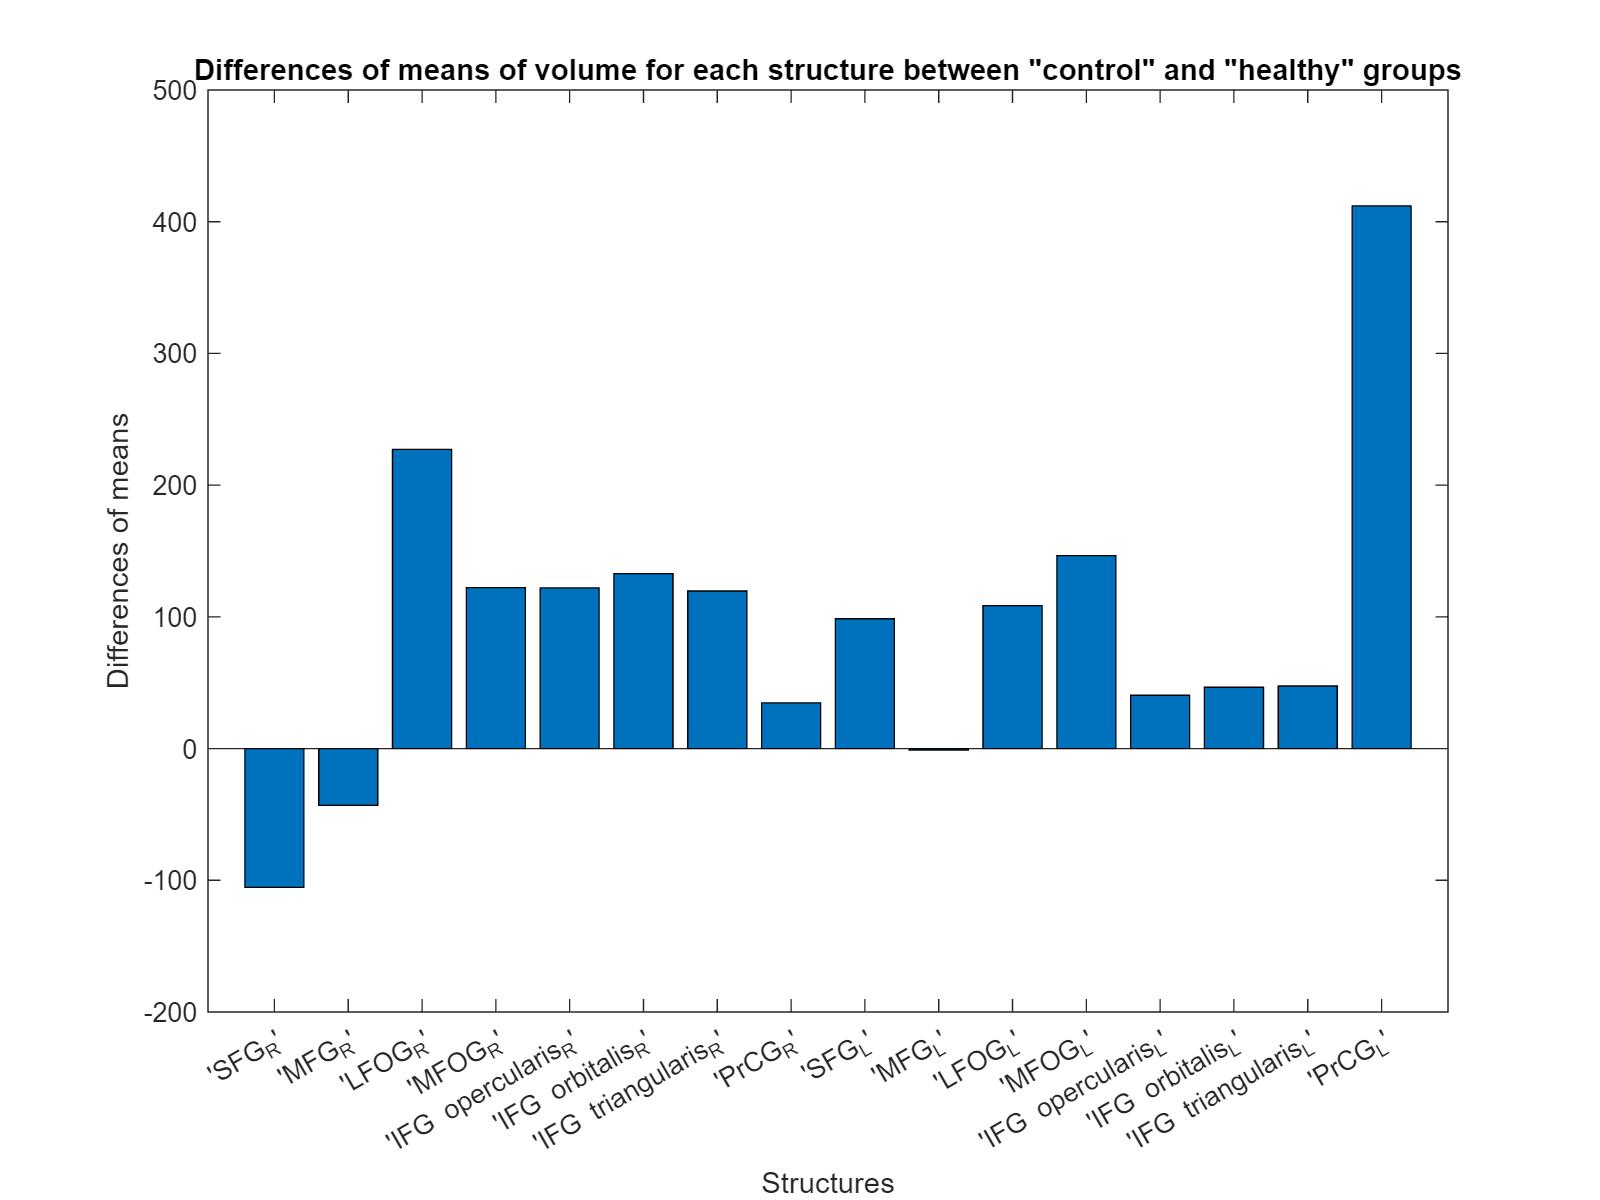

figure('Position', [100, 100, 800, 600]);
X = categorical(ROI_name);
b = bar(reordercats(X,ROI_name),mean(volume_disease(:,myROI_index))-mean(volume_normal(:,myROI_index)));

title('Differences of means of volume for each structure between "control" and "healthy" groups');
xlabel('Structures');
ylabel('Differences of means');

saveas(gcf, 'differences of means.png');

Last, a barcode for the patient is created after analysis using MRICloud.

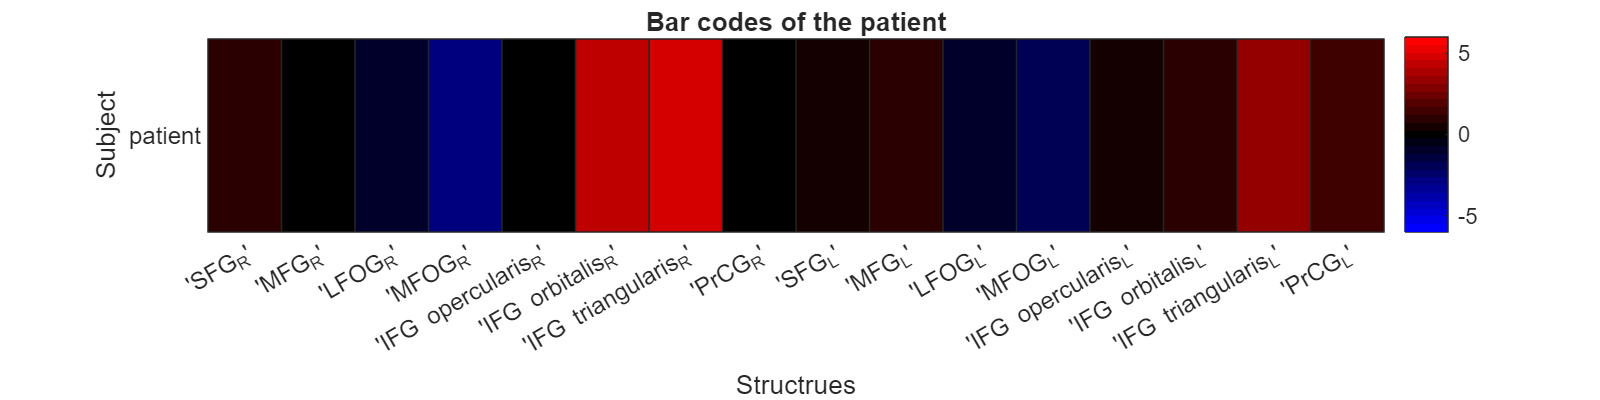

MNI_table = readtable("data_raw.xlsx");
volume_MNI = table2array(MNI_table(:,2));
volume_MNI = volume_MNI([2,4,6,8,10,12,14,16,1,3,5,7,9,11,13,15])';
z_score_MNI = (volume_MNI - mean_normal(myROI_index)) ./ SD_normal(myROI_index);

figure('Position', [100, 100, 800, 200]);
h = heatmap(ROI_name, {'patient'}, z_score_MNI, 'Colormap', colormap, 'CellLabelColor', 'none');
clim([-maxdata, maxdata]);
title('Bar codes of the patient');
xlabel('Structrues');
ylabel('Subject');

saveas(gcf, 'Barcodes for the patient.png');